# Generate our Bell Parameter off the correlations:

## Lists:

phi = 0:pi/180:pi;
E_list = 0.*phi;

## Parameters:

$\lambda$ = L - mode occupancy.  

$\phi$ - phase of interferometer.  

$T_{max}$ - maximum number of generated particle

cycles = C - number of simulated tests used to perform correlation.

QE = R - retention rate / quantum efficiency.

dark_rate = D - fraction of tests which return a non-experimental count.

$\sigma$ = B - decay width of gaussian blur in detection uncertainty.

R - radius of $He_4$ halos.

phys - Quantum ('Q') or Classical ('C') physics to be used.

$Y_{\text{bias}}$ - with a classical beam splitter, the R.H.S. bias towards Y (up)

$X_{\text{bias}}$ -         "             "                      , the L.H.S. bias towards X (up)

lambda = 0.2;
% phi =   ;
Tmax = 10;
cycles = 1E4;
QE = 100;
dark_rate = 0;
sigma = 0;
R = 1;
phys = 'Q';

## Evaluation for each phase:

percent = 0.5525

percent = 1.1050

percent = 1.6575

percent = 2.2099

percent = 2.7624

percent = 3.3149

percent = 3.8674

percent = 4.4199

percent = 4.9724

percent = 5.5249

percent = 6.0773

percent = 6.6298

percent = 7.1823

percent = 7.7348

percent = 8.2873

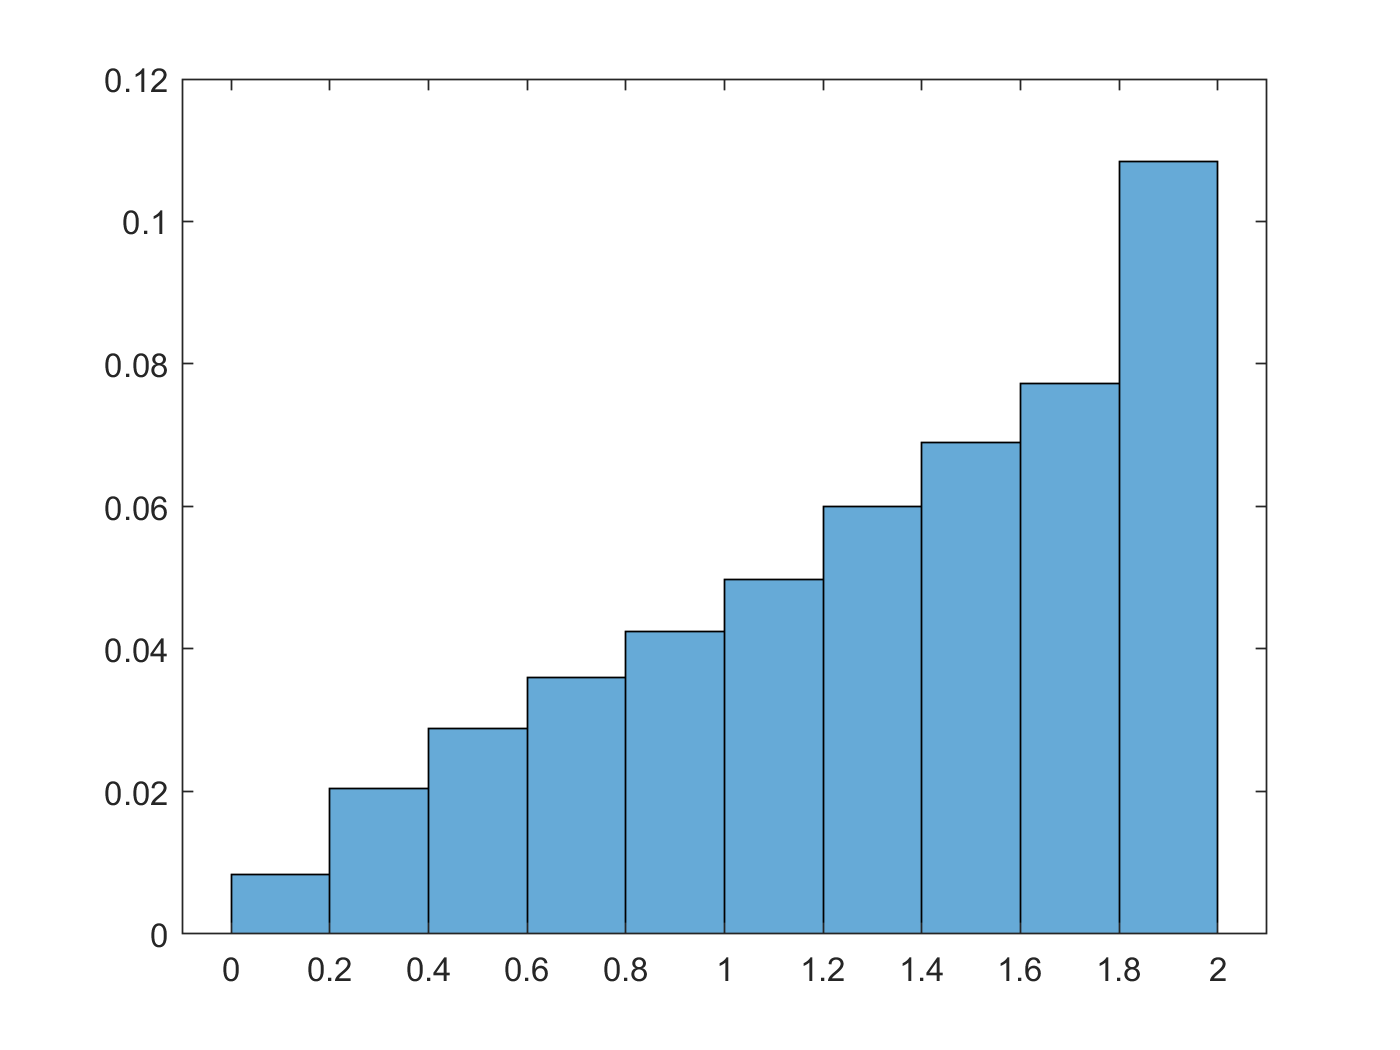

percent = 8.8398

for p = 1:length(phi)
    [g_side, g_diag] = correlators2(lambda,phi(p),Tmax,cycles,QE,dark_rate,sigma,R,phys,0,0);
    E_list(p) = (g_side - g_diag)/(g_side+g_diag);
    percent = 100*p/length(phi)
end

## Generate Plot / Image:

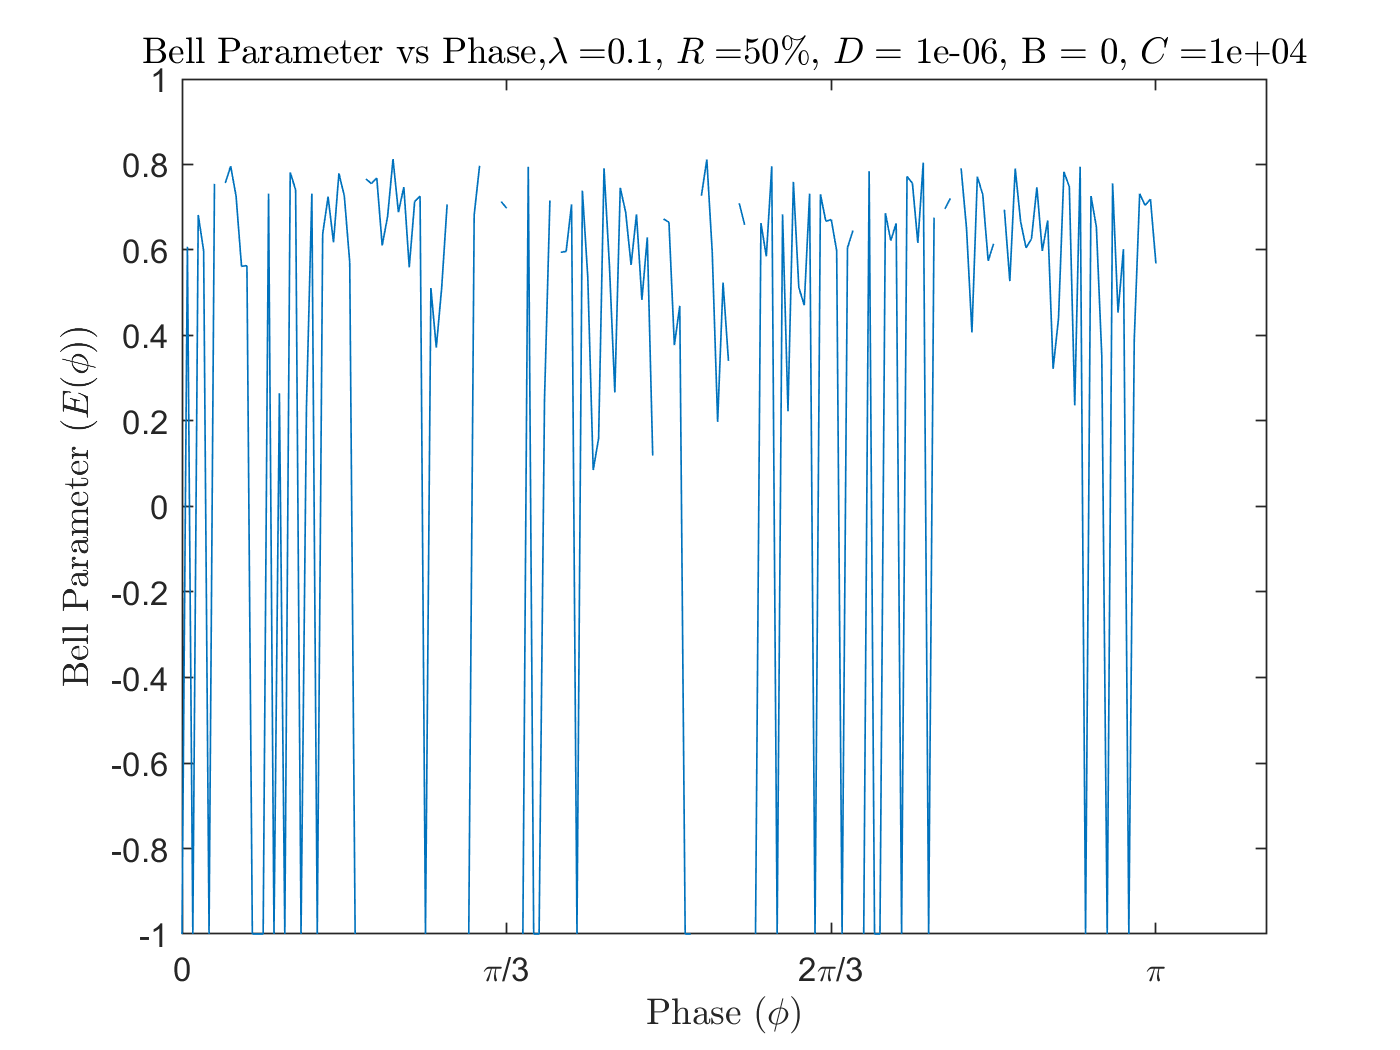

plot(phi,E_list)
xticks([0,pi/3,2*pi/3,pi,4*pi/3,5*pi/3,2*pi])
xticklabels(["0","\pi/3","2\pi/3","\pi","4\pi/3","5\pi/3","2\pi"])
xlabel("Phase ($\phi$)","Interpreter",'latex')
ylabel("Bell Parameter ($E(\phi)$)","Interpreter","latex")
title("Bell Parameter vs Phase,$\lambda = $" + string(lambda) + ", $R =$" + string(QE)+"\%, $D = $" + " "+num2str(dark_rate, '%.0e')+", B = "+string(sigma)+", $C = $"+num2str(cycles,'%.0e'),"Interpreter","latex")

## Write to File:

A = [phi; E_list];
name = erase('R'+string(QE)+'_D'+num2str(dark_rate,'%.0e')+'_B'+string(sigma)+'_C'+num2str(cycles,'%.0e')+'_L'+string(lambda),'.');
data = fopen(name+'.txt','w');
fprintf(data,'%6s %12s\n','\phi','E(\phi)');
fprintf(data,'%6.4f %12.8f\n',A);
fclose(data);